clear
clc

% Initializing kero variables
KtL = 14.425; % Tank length
KtD = 6; % Tank diameter
KwM = 11.524; % Wet mass
KdM = 3.245; % Dry mass
Kdensity = 0.02962444; % Propellant density
Kmdot = 2.535 / 2.2; % Mass flow rate

% Initializing lox variables
LtL = 23.289; % Tank length
LtD = 6; % Tank diameter
LwM = 25.353; % Wet mass
LdM = 5.239; % Dry mass
Ldensity = 0.03964103242; % Propellant density
Lmdot = 2.535; % Mass flow rate

time = 10; % Burn time
burntime = linspace(0,time,11);


% Calling function
KeroCoGs = getCoG(KwM, KdM, time, KtL, KtD, Kdensity, Kmdot);
T = array2table(KeroCoGs,"VariableNames",{'Time (s)','CoG (in from base of tank)'});
T = table(T,'VariableNames',{'Kero CG'});
disp(T)

                   Kero CG                
    Time (s)    CoG (in from base of tank)
    ______________________________________

        0                 7.7575          
        1                 7.2206          
        2                 6.7116          
        3                  6.239          
        4                 5.8153          
        5                 5.4591          
        6                 5.2003          
        7                 5.0889          
        8                 5.2168          
        9                 5.7722          
       10                 7.2101          



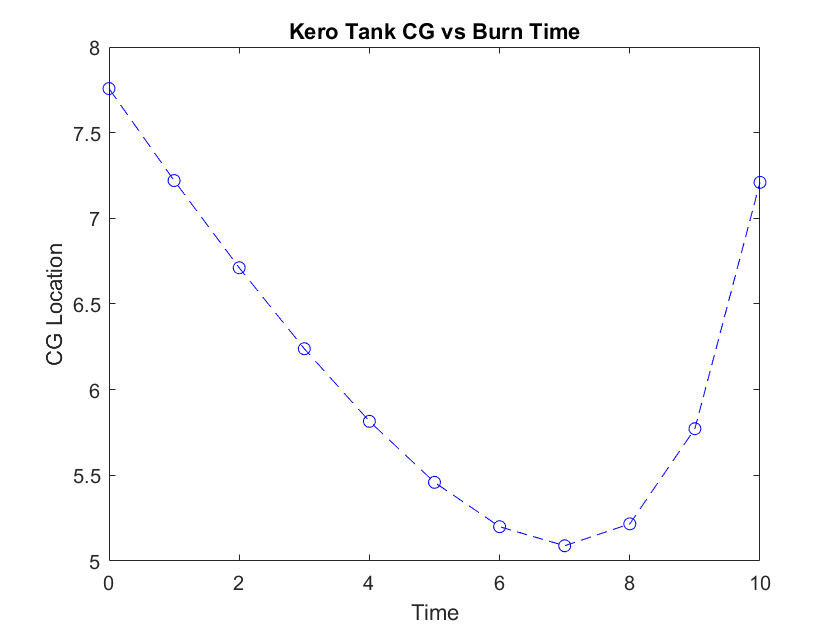

plot(burntime, KeroCoGs(:,2),'b--o')
title("Kero Tank CG vs Burn Time")
ylabel('CG Location')
xlabel('Time')

LOXCoGs = getCoG(LwM, LdM, time, LtL, LtD, Ldensity, Lmdot);
T = array2table(LOXCoGs,"VariableNames",{'Time (s)','CoG (in from base of tank)'});
T = table(T,'VariableNames',{'LOX CG'});
disp(T)

                    LOX CG                
    Time (s)    CoG (in from base of tank)
    ______________________________________

        0                 12.773          
        1                 11.832          
        2                 10.929          
        3                 10.077          
        4                 9.2929          
        5                 8.6073          
        6                 8.0684          
        7                 7.7632          
        8                 7.8639          
        9                 8.7675          
       10                 11.639          



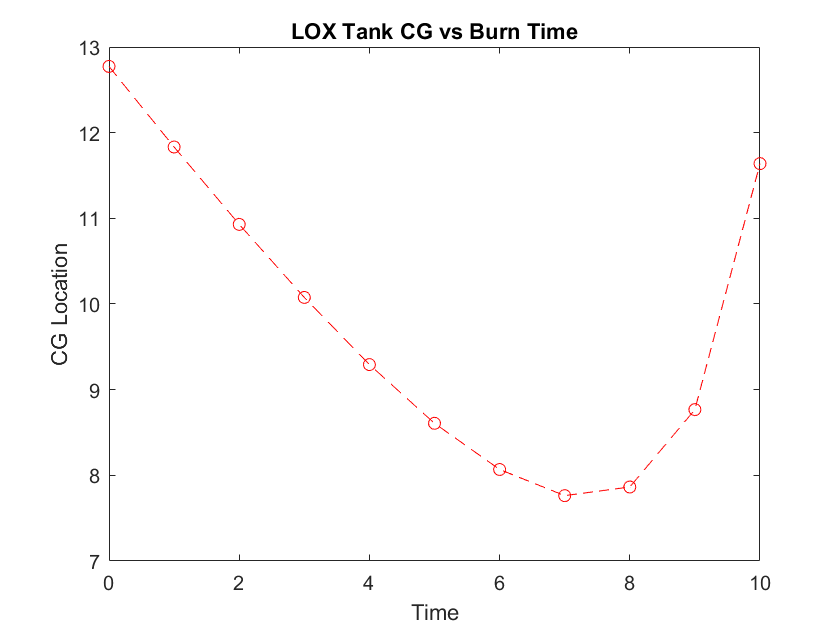

plot(burntime, LOXCoGs(:,2),'r--o')
title("LOX Tank CG vs Burn Time")
ylabel('CG Location')
xlabel('Time')

function [CoGs] = getCoG(wM, dM, time, tL, tD, density, mdot)

Vo = (wM / density) * (1.15); % Finds initial propellant volume
tCG = dM * (tL/2); % Finds constant W1d1/tank term in COG equation
tR = tD / 2; % Converts tank diameter to radius

V = zeros(1,(round(time) + 1)); % Preallocates arrays for variables that change with time
mp = V;
d = V;
COG = V;
% Done preallocating (for now), it's loop time yippee
for t = (0:time)
    mp(t+1) = wM - (mdot * t); % Finds propellant mass at t
    d(t+1) = ((Vo - ((mdot/density)*t)) / (2 * pi * ((tR) ^ 2))); % Finds the distance term for the propellant at t
    COG(t+1) = ((tCG + (mp(t+1) * d(t+1))) / (dM + mp(t+1))); % Finds (finally) the center of gravity at t
end
CoGs = zeros((round(time) + 1),2); % Preallocates space for CoGs table
CoGs(:,1) = 0:(round(time)); % Makes column of time values
CoGs(:,2) = COG; % Makes column of CoG values



end